17.40

clear
close all
clc

mot.k = 5.2;
mot.T = 0.03;
a = 0.17;
tau = 0.015;
N = 3;
Ts = 0.01;

Pc = tf([mot.k], [mot.T 1 0]);
Pd = c2d(Pc, Ts, "zoh");

z = tf('z', Ts);
s = (z - 1) / Ts;
CdFE = minreal((1 + tau * s) / (s * (1 + a * tau * s)), 1e-6);
s = (1 - z^-1) / Ts;
CdBE = minreal((1 + tau * s) / (s * (1 + a * tau * s)), 1e-6);
Cs = tf([tau 1], [a * tau 1 0]);
CdTU = c2d(Cs, Ts, "tustin");

H = (1 - z^-N) / (N * Ts);

Studio il caso di controllore discretizzato con metodo di Eulero in avanti

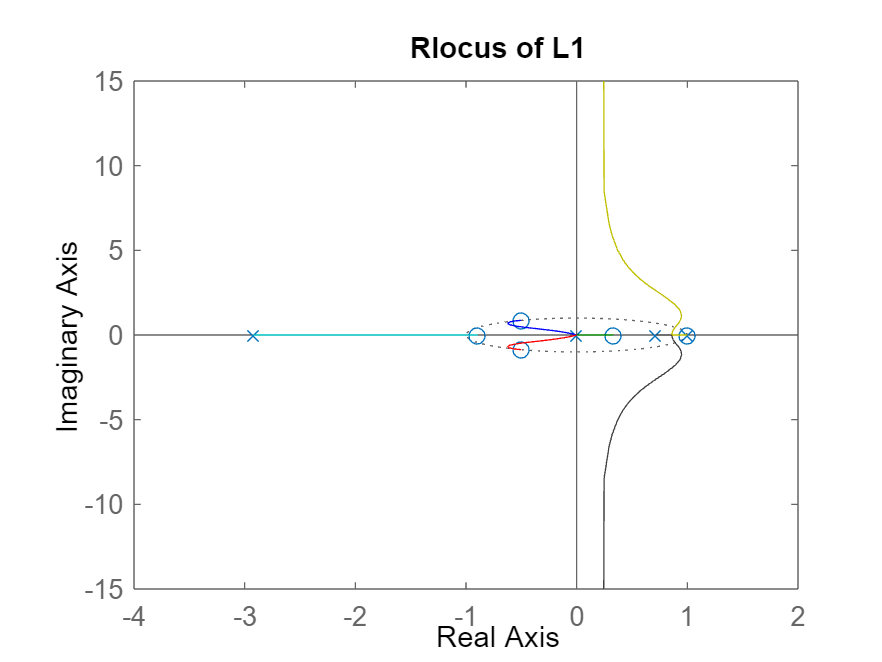

L1 = CdFE * Pd * H;
figure(1)
rlocus(L1)
title("Rlocus of L1")

kcrit1 = margin(L1)

kcrit = 15.5632

Il sistema è instabile per ogni k non negativo

Studio il caso di controllore discretizzato con metodo di Eulero all'indietro

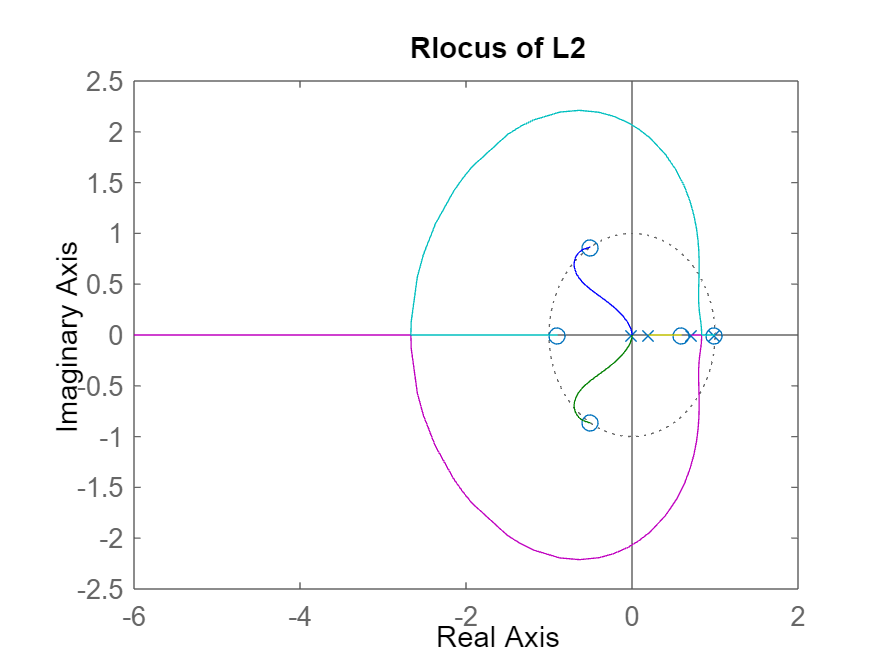

L2 = CdBE * Pd * H;
figure(2)
rlocus(L2)
title("Rlocus of L2")

kcrit2 = margin(L2)

kcrit2 = 20.5369

Ho dei valori di k per cui il sistema è BIBO stabile

Studio il caso di controllore discretizzato con metodo di Tustin

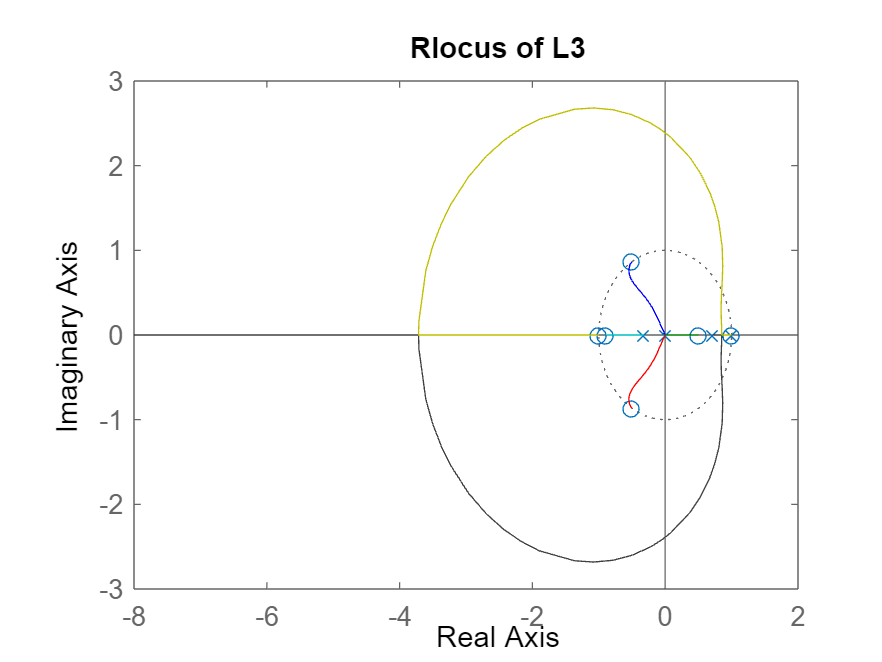

L3 = CdTU * Pd * H;
figure(3)
rlocus(L3)
title("Rlocus of L3")

kcrit3 = margin(L3)

kcrit3 = 18.4912

Ho dei valori di k per cui il sistema è BIBO stabile

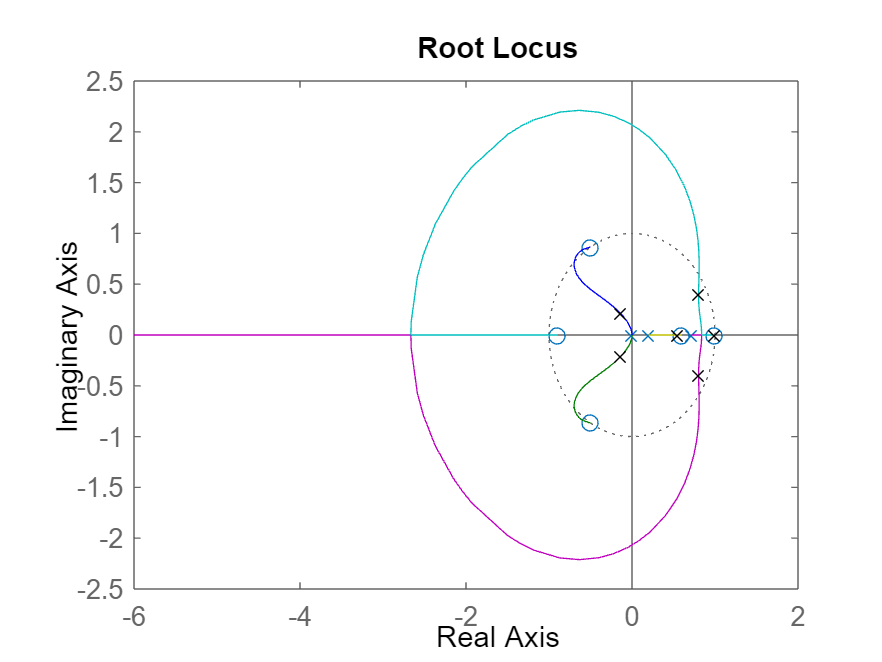

k2 = kcrit2 / 2;
T2 = minreal(feedback(k2 * CdBE * Pd, H), 1e-6);
poles2 = pole(T2);
close all
figure(4)
hold on
rlocus(L2)
plot(real(poles2), imag(poles2), "kx")

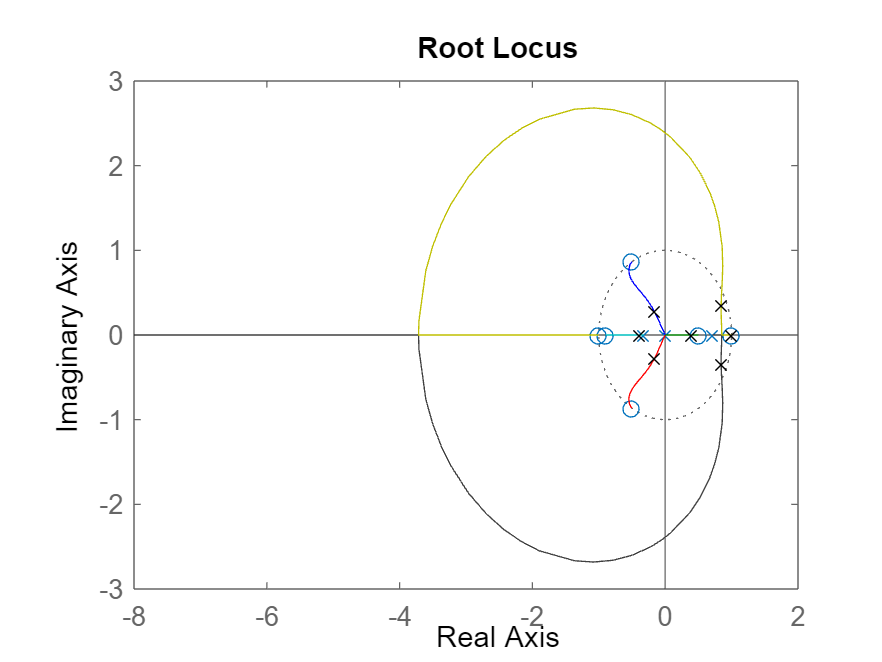

k3 = kcrit3 / 2;
T3 = minreal(feedback(k3 * CdTU * Pd, H), 1e-6);
poles3 = pole(T3);
close all
figure(5)
hold on
rlocus(L3)
plot(real(poles3), imag(poles3), "kx")

17.57